# Final Project

Lino De Ros, Connor Emmons, Dylan Payne

## Dependencies

clear; clc;
% rlspecs.m
% bodespecs.m
% MagPhase.m
% step2tf.m

## System Specifications

PO = 13; %Percent
t_r = 0.4; %Seconds
bw = 4; %rad/s
mag_rp = 3; %db

## Data Visualization and Transfer Function

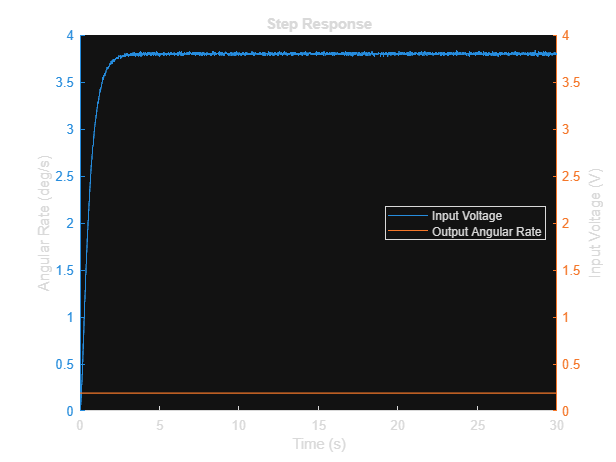

data = load('step_data.mat'); %Loads the data


% Recreates the scope graph, plots both input and output vs. time
figure
hold on
xlim([0 30]) %Lock the x-axis

yyaxis left %Specifies the left y-axis, which is the input
ylim([0 4])
plot(data.out.tout, data.out.rate)
ylabel("Angular Rate (deg/s)")

yyaxis right %Specifies the right y-axis, which is the output
ylim([0 4])
plot(data.out.tout, data.out.input)
ylabel("Input Voltage (V)")

title("Step Response")
xlabel("Time (s)")
legend("Input Voltage", "Output Angular Rate", "Location", "east")
hold off

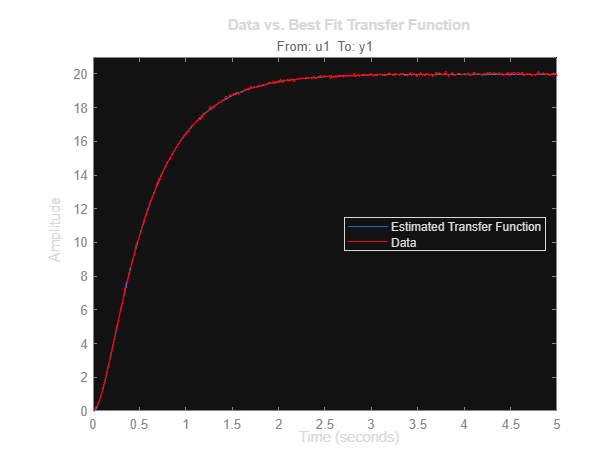



% Generates the best fit transfer function and plots it against the data
figure
[G, z, p, k] = step2tf(data.out.tout, data.out.input, data.out.rate, 2, 0, 1);
axis([0 5 0 21]) %Lock the axes

title("Data vs. Best Fit Transfer Function")
legend("Estimated Transfer Function", "Data", "Location", "east")



% Define the transfer function for angular rate (determined from the data)
% and the transfer function for angular position (integral of angular rate)
G_rate = G;
G_position = G_rate*zpk([], [0], 1);

G_ramp = tf(1, [1,0]); %For testing against ramp input
s = tf([1,0], 1); %Free s

MathWorks::System::IUserException in WebControllerFactory::create(): [Unrecognized method, property, or field 'ViewModel' for class 'handle'.

Error in matlab.ui.internal.componentframework.WebComponentController/getParentView (line 476)
            parentView = parentController.ViewModel;

Error in 

## Lead Compensator - Root Locus Design

%rlspecs(G_position, PO, t_r, bw)


% Adjustable Values
s_op = -3 + 4i;
num_control_rl_dd = 2;
num_control_rl_bi = num_control_rl_dd;


% Find the gain and angle of the open loop transfer function evaluated at s
[~, Gain_p_rl, Angle_p_rl] = MagPhase(G_position, s_op);

Gain_c_rl = 1/Gain_p_rl;
Angle_c_rl = -180 - Angle_p_rl + 360*(-180 - Angle_p_rl < 0); %Only adds 360 if Angle_c would be negative

### Drop-Down Method

z = abs(real(s_op)); %For the drop-down method, z is the real component of s
p = imag(s_op)*tand(Angle_c_rl/num_control_rl_dd) + z; %p is based on the angle required by the controller

k = Gain_c_rl*abs((s_op + p)^num_control_rl_dd)/abs((s_op + z)^num_control_rl_dd);

G_control_rl_dd = zpk(-z*ones(1, num_control_rl_dd), -p*ones(1, num_control_rl_dd), k)

G_control_rl_dd =
 
  0.80271 (s+3)^2
  ---------------
    (s+6.922)^2
 
Continuous-time zero/pole/gain model.
Model Properties



%rlspecs(G_control_rl_dd*G_position, PO, t_r, bw)

G_lead_rl_dd = feedback(G_control_rl_dd*G_position, 1);

% Parameter Validation
[mag_rl_dd, ~, omega_rl_dd] = bode(G_lead_rl_dd, [0:0.0001:10]);
mag_rl_dd = 20*log10(mag_rl_dd);

rise_time_rl_dd = stepinfo(G_lead_rl_dd).RiseTime

rise_time_rl_dd = 0.4375

overshoot_rl_dd = stepinfo(G_lead_rl_dd).Overshoot

overshoot_rl_dd = 8.4472

bandwidth_rl_dd = omega_rl_dd(abs(mag_rl_dd - (mag_rl_dd(:,:,1) - 3)) == min(abs(mag_rl_dd - (mag_rl_dd(:,:,1) - 3))))

bandwidth_rl_dd = 4.9535

peak_mag_rl_dd = max(mag_rl_dd) - mag_rl_dd(:,:,1)

peak_mag_rl_dd = 0.2631

ramp_error_rl_dd = 1/evalfr(minreal(G_control_rl_dd*G_position*s), 0)

ramp_error_rl_dd = 0.3316

### Bisector Method

[~, ~, gamma] = MagPhase(zpk(0, [], 1), s_op); %Find the angle of the operating point
theta_z = gamma/2 + (Angle_c_rl/num_control_rl_bi)/2;
theta_p = gamma/2 - (Angle_c_rl/num_control_rl_bi)/2;

z = imag(s_op)/tand(theta_z) + abs(real(s_op)); %z and p are both based on the angle required by the controller
p = imag(s_op)/tand(theta_p) + abs(real(s_op)); %^

k = Gain_c_rl*abs((s_op + p)^num_control_rl_bi)/abs((s_op + z)^num_control_rl_bi);

G_control_rl_bi = zpk(-z*ones(1, num_control_rl_bi), -p*ones(1, num_control_rl_bi), k)

G_control_rl_bi =
 
  0.93718 (s+3.304)^2
  -------------------
      (s+7.567)^2
 
Continuous-time zero/pole/gain model.
Model Properties



%rlspecs(G_control_rl_bi*G_position, PO, t_r, bw)

G_lead_rl_bi = feedback(G_control_rl_bi*G_position, 1);

% Parameter Validation
[mag_rl_bi, ~, omega_rl_bi] = bode(G_lead_rl_bi, [0:0.0001:10]);
mag_rl_bi = 20*log10(mag_rl_bi);

rise_time_rl_bi = stepinfo(G_lead_rl_bi).RiseTime

rise_time_rl_bi = 0.3912

overshoot_rl_bi = stepinfo(G_lead_rl_bi).Overshoot

overshoot_rl_bi = 13.2441

bandwidth_rl_bi = omega_rl_bi(abs(mag_rl_bi - (mag_rl_bi(:,:,1) - 3)) == min(abs(mag_rl_bi - (mag_rl_bi(:,:,1) - 3))))

bandwidth_rl_bi = 5.4192

peak_mag_rl_bi = max(mag_rl_bi) - mag_rl_bi(:,:,1)

peak_mag_rl_bi = 0.7690

ramp_error_rl_bi = 1/evalfr(minreal(G_control_rl_bi*G_position*s), 0)

ramp_error_rl_bi = 0.2798

### Lag Compensator - Drop Down

% Adjustable Values
k_req = 20;


z = -0.1*real(s_op);
p = (1/ramp_error_rl_dd)*z/k_req;

G_lag_control_rl_dd = zpk(-z, -p, 1)

G_lag_control_rl_dd =
 
    (s+0.3)
  -----------
  (s+0.04523)
 
Continuous-time zero/pole/gain model.
Model Properties



%rlspecs(G_lag_control_rl_dd*G_control_rl_dd*G_position, PO, t_r, bw)

G_lead_lag_rl_dd = feedback(G_lag_control_rl_dd*G_control_rl_dd*G_position, 1);

% Parameter Validation
[mag_rl_dd_lag, ~, omega_rl_dd_lag] = bode(G_lead_lag_rl_dd, [0:0.0001:10]);
mag_rl_dd_lag = 20*log10(mag_rl_dd_lag);

rise_time_rl_dd_lag = stepinfo(G_lead_lag_rl_dd).RiseTime

rise_time_rl_dd_lag = 0.4050

overshoot_rl_dd_lag = stepinfo(G_lead_lag_rl_dd).Overshoot

overshoot_rl_dd_lag = 17.5274

bandwidth_rl_dd_lag = omega_rl_dd_lag(abs(mag_rl_dd_lag - (mag_rl_dd_lag(:,:,1) - 3)) == min(abs(mag_rl_dd_lag - (mag_rl_dd_lag(:,:,1) - 3))))

bandwidth_rl_dd_lag = 5.0774

peak_mag_rl_dd_lag = max(mag_rl_dd_lag) - mag_rl_dd_lag(:,:,1)

peak_mag_rl_dd_lag = 1.0993

ramp_error_rl_dd_lag = 1/evalfr(minreal(G_lag_control_rl_dd*G_control_rl_dd*G_position*s), 0)

ramp_error_rl_dd_lag = 0.0500

### Lag Compensator - Bisector

% Adjustable Values
k_req = 20;


z = -0.1*real(s_op);
p = (1/ramp_error_rl_bi)*z/k_req;

G_lag_control_rl_bi = zpk(-z, -p, 1)

G_lag_control_rl_bi =
 
    (s+0.3)
  -----------
  (s+0.05361)
 
Continuous-time zero/pole/gain model.
Model Properties



%rlspecs(G_lag_control_rl_bi*G_control_rl_bi*G_position, PO, t_r, bw)

G_lead_lag_rl_bi = feedback(G_lag_control_rl_bi*G_control_rl_bi*G_position, 1);

% Parameter Validation
[mag_rl_bi_lag, ~, omega_rl_bi_lag] = bode(G_lead_lag_rl_bi, [0:0.0001:10]);
mag_rl_bi_lag = 20*log10(mag_rl_bi_lag);

rise_time_rl_bi_lag = stepinfo(G_lead_lag_rl_bi).RiseTime

rise_time_rl_bi_lag = 0.3681

overshoot_rl_bi_lag = stepinfo(G_lead_lag_rl_bi).Overshoot

overshoot_rl_bi_lag = 21.6681

bandwidth_rl_bi_lag = omega_rl_bi_lag(abs(mag_rl_bi_lag - (mag_rl_bi_lag(:,:,1) - 3)) == min(abs(mag_rl_bi_lag - (mag_rl_bi_lag(:,:,1) - 3))))

bandwidth_rl_bi_lag = 5.5145

peak_mag_rl_bi_lag = max(mag_rl_bi_lag) - mag_rl_bi_lag(:,:,1)

peak_mag_rl_bi_lag = 1.5456

ramp_error_rl_bi_lag = 1/evalfr(minreal(G_lag_control_rl_bi*G_control_rl_bi*G_position*s), 0)

ramp_error_rl_bi_lag = 0.0500

## Lead Compensator - Bode Design

%bodespecs(G_position, PO, t_r, bw, mag_rp)


% Adjustable Values
omega_op = 4;
num_control_bd = 2;
Pm_offset = 5;


[~, Gain_p_bd, Angle_p_bd] = MagPhase(G_position, omega_op*i);
zet = -log(PO/100)/sqrt(pi^2+log(PO/100)^2); %Calculate zeta based on the PO
Pm = atan(2*zet/sqrt(-2*zet^2+sqrt(1+4*zet^4)))*180/pi; %Calculate Phase Margin based on zeta

Gain_c_bd = 1/Gain_p_bd;
Angle_c_bd = Pm + Pm_offset - 180 - Angle_p_bd +...
    360*(Pm + Pm_offset - 180 - Angle_p_bd < 0); %Only adds 360 if Angle_c would be negative

alpha = (1 + sind(Angle_c_bd/num_control_bd))/(1 - sind(Angle_c_bd/num_control_bd));

z = omega_op/sqrt(alpha);
p = omega_op*sqrt(alpha);

k = Gain_c_bd*abs((s_op + p)^num_control_bd)/abs((s_op + z)^num_control_bd);

G_control_bd = zpk(-z*ones(1, num_control_bd), -p*ones(1, num_control_bd), k)

G_control_bd =
 
  0.94448 (s+2.312)^2
  -------------------
      (s+6.919)^2
 
Continuous-time zero/pole/gain model.
Model Properties



%bodespecs(G_control_bd*G_position, PO, t_r, bw, mag_rp)

G_lead_bd = feedback(G_control_bd*G_position, 1);

% Parameter Validation
[mag_bd, ~, omega_bd] = bode(feedback(G_lead_bd, 1), [0:0.0001:10]);
mag_bd = 20*log10(mag_bd);

rise_time_bd = stepinfo(G_lead_bd).RiseTime

rise_time_bd = 0.5807

overshoot_bd = stepinfo(G_lead_bd).Overshoot

overshoot_bd = 0

bandwidth_bd = omega_bd(abs(mag_bd - (mag_bd(:,:,1) - 3)) == min(abs(mag_bd - (mag_bd(:,:,1) - 3))))

bandwidth_bd = 8.8840

peak_mag_bd = max(mag_bd) - mag_bd(:,:,1)

peak_mag_bd = 2.2092

ramp_error_bd = 1/evalfr(minreal(G_control_bd*G_position*s), 0)

ramp_error_bd = 0.4740

### Lag Compensator

% Adjustable Values
k_req = 20;


z = 0.1*omega_op;
p = (1/ramp_error_bd)*z/k_req;

G_lag_control_bd = zpk(-z, -p, 1)

G_lag_control_bd =
 
   (s+0.4)
  ----------
  (s+0.0422)
 
Continuous-time zero/pole/gain model.
Model Properties



%rlspecs(G_lag_control_bd*G_control_bd*G_position, PO, t_r, bw)

G_lead_lag_bd = feedback(G_lag_control_bd*G_control_bd*G_position, 1);

% Parameter Validation
[mag_bd_lag, ~, omega_bd_lag] = bode(G_lead_lag_bd, [0:0.0001:10]);
mag_bd_lag = 20*log10(mag_bd_lag);

rise_time_bd_lag = stepinfo(G_lead_lag_bd).RiseTime

rise_time_bd_lag = 0.4544

overshoot_bd_lag = stepinfo(G_lead_lag_bd).Overshoot

overshoot_bd_lag = 9.2745

bandwidth_bd_lag = omega_bd_lag(abs(mag_bd_lag - (mag_bd_lag(:,:,1) - 3)) == min(abs(mag_bd_lag - (mag_bd_lag(:,:,1) - 3))))

bandwidth_bd_lag = 4.7658

peak_mag_bd_lag = max(mag_bd_lag) - mag_bd_lag(:,:,1)

peak_mag_bd_lag = 0.9135

ramp_error_bd_lag = 1/evalfr(minreal(G_lag_control_bd*G_control_bd*G_position*s), 0)

ramp_error_bd_lag = 0.0500